## System Parameters

SYSTEM.F_res_sec = 264e3;                 % Secondary resonant frequency with topload, Hz
SYSTEM.F_res_pri = SYSTEM.F_res_sec;      % Primary resonant frequency, Hz
SYSTEM.PRF_fmax = 200;                    % Max pulse repetition frequency from interrupter, Hz
SYSTEM.PRF_DC_max = 8;                    % Max duty cycle of PRF interrupter signal, %
% Max on-time of PRF interrupter signal, sec
SYSTEM.PRF_Ton_max = (1/SYSTEM.PRF_fmax) * (SYSTEM.PRF_DC_max/100);
SYSTEM.Tc_ambient = 22;                   % Ambient temperature, Celsius

SYSTEM.OCD_max = 300;                     % Max supported OCD limit, A  

% Current sense ADC sampling frequency, set to at least 10x of resonant
% frequency (with some slop added), Hz
SYSTEM.ADC.f_samp = 10*SYSTEM.F_res_pri;

## Primary Tank Params

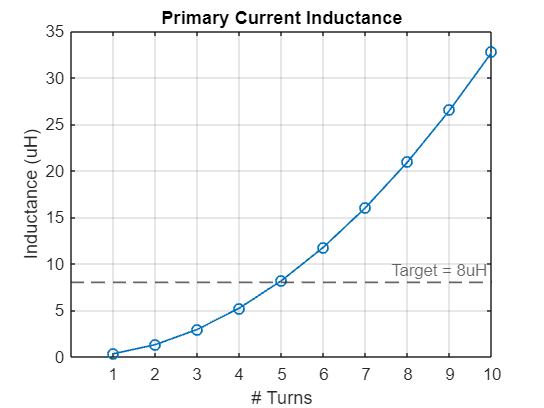

PRI_TANK.Lp = 7732.2910e-9;     % Primary tank coil inductance, H

Primary_coil_geometry = "flat spiral";

if Primary_coil_geometry == "flat spiral"
    rho_primary_coil = 0.017e-6;    % C110 copper, Ohm/m 
    Pri_coil_conductor_width = inchToMeter(1);  % Primary coil width, m
    Pri_coil_conductor_spacing = inchToMeter(0.5); % Primary coil spacing, m 
    Pri_coil_conductor_thickness = 1.6e-3;      % Primary coil thickness, m

    Pri_coil_outer_diam = 539.65e-3;            % Primary coil outer diameter, m
    Pri_coil_inner_diam = 145.95e-3;            % Primary coil inner diameter, m
    Pri_coil_num_turns = 5;                     % Primary coil number of turns
    
    % Compute planar spiral inductance
    [Lmw, Lcs, Lmf] = computePlanarSpiralInductance(Pri_coil_outer_diam, Pri_coil_inner_diam, Pri_coil_num_turns, Pri_coil_conductor_width, Pri_coil_conductor_spacing, "circular");
    if Lcs ~= -1
       PRI_TANK.Lp = Lcs;  % Primary tank coil inductance, H
    end
    
    % Sweep number of turns
    n_turns = 1:10;
    Lcs_sweep = zeros(size(n_turns));
    warning('off', 'all');
    for i=1:length(n_turns)
        [Lmw_, Lcs_sweep(i), Lmf_] = computePlanarSpiralInductance(Pri_coil_outer_diam, Pri_coil_inner_diam, n_turns(i), Pri_coil_conductor_width, Pri_coil_conductor_spacing, "circular");
    end
    warning('on', 'all');
    
    lineWidth = 1;
    figure();
    plot(n_turns,Lcs_sweep*1e6,'-o','LineWidth',lineWidth);
    grid on;
    ylabel("Inductance (uH)");
    yline(8,'--',"Target = 8uH","LineWidth",lineWidth);
    xlabel("# Turns");
    xticks([n_turns]);
    title('Primary Coil Inductance');

    % Approximate ESR of primary coil
    Pri_coil_len = ((4989.911 + 5787.145)/2)/1000;     % length of primary coil (m) (see below)
    % Resistivity of copper
    rho_copper = 1.68e-8; % Ohm*m
    % Primary coil cross-sectional area
    pri_col_A = Pri_coil_conductor_width*Pri_coil_conductor_thickness; % m^2
    % ESR of primary coil
    PRI_TANK.ESR_Pri = rho_copper*(Pri_coil_len/pri_col_A);
    fprintf("Primary coil ESR: %0.2f mOhm",PRI_TANK.ESR_Pri*1e3);
end

#### Flat Spiral Dims

Length of spiral (inside edge): 4989.911 mm

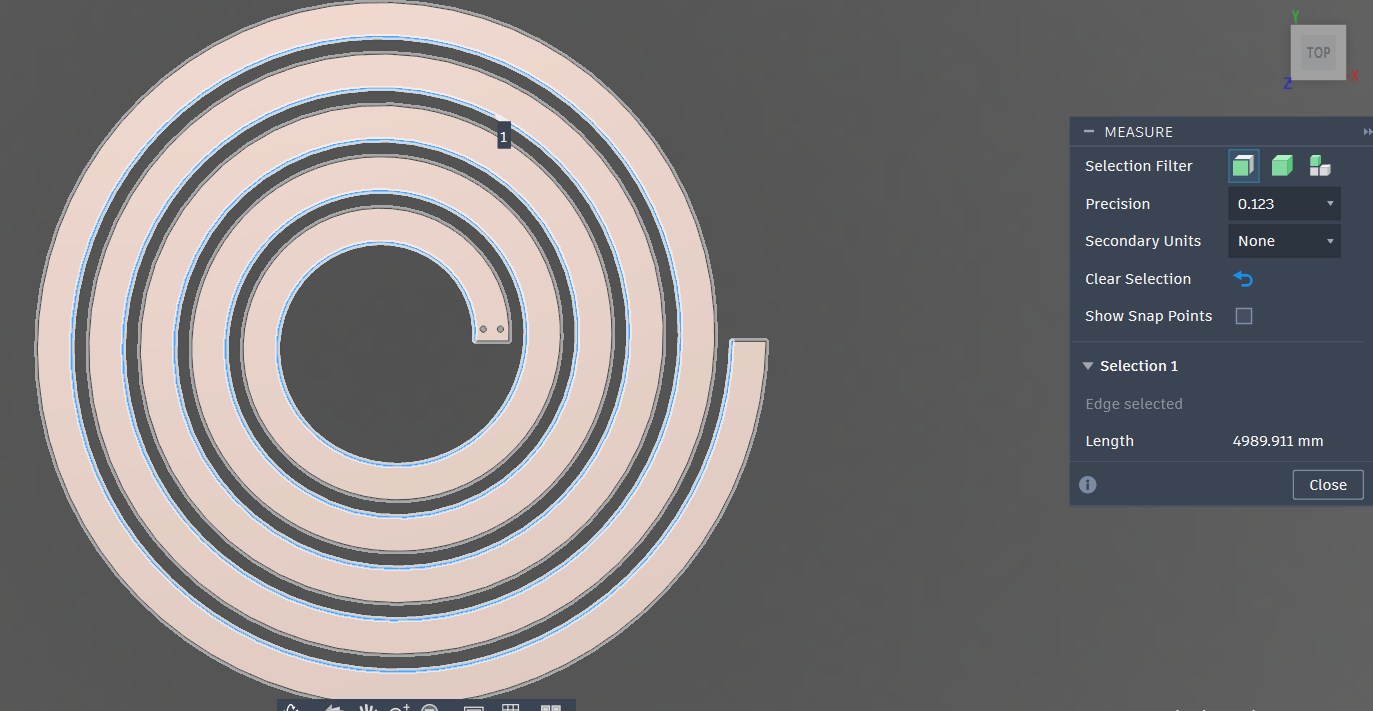

Length of spiral (inside edge): 5787.145 mm

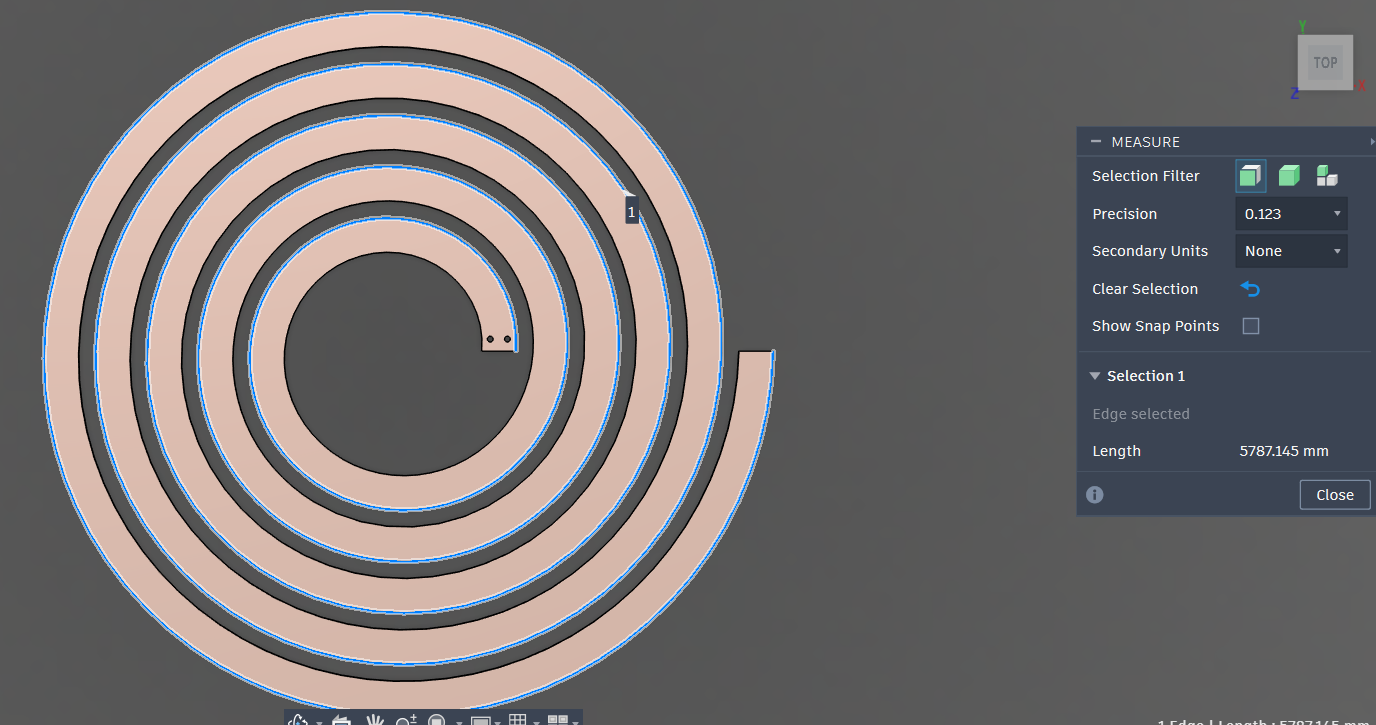

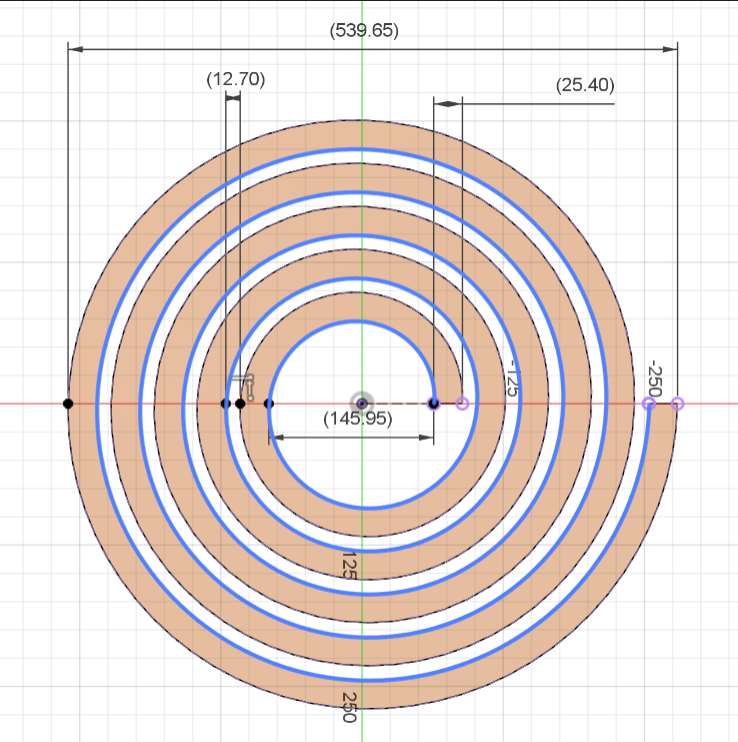

#### MMC Capacitor

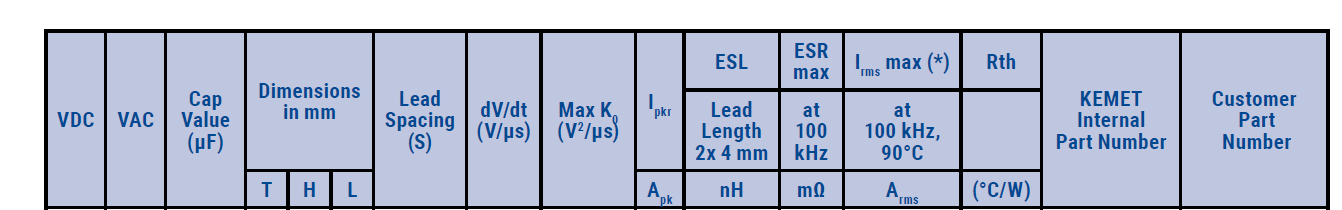

MMC_cap_mfgpn = "R75TR318050H2J";    

switch MMC_cap_mfgpn
    case "R75TR318050H2J"
        MMC_BANK.Cap_price =  2.78;   % Price of MMC capacitor, USD
        MMC_BANK.Cap = 0.18e-6;      % MMC capacitor capacitance, F
        MMC_BANK.Cap_ESR = 6.2e-3;       % MMC capacitor ESR, Ohm
        MMC_BANK.Cap_VDC_rating = 1600;  % MMC capacitor VDC rating, V
        MMC_BANK.Cap_VAC_rating = 650;   % MMC capacitor VAC rating, V
        MMC_BANK.Cap_Ipk_rating = 270;          % MMC capacitor Peak Current rating, A
        MMC_BANK.Cap_dVdt_rating = 1500;        % MMC capacitor max dV/dt (voltage slope) rating, V/us
        MMC_BANK.Cap_Tc_max = 125;       % Max operating temperature, Celsius
        MMC_BANK.Cap_Rth = 28.0;         % Thermal resistance, C/W
        MMC_BANK.Np = 2;                 % Number of parallel strings of MMC capacitors. Set to -1 to auto compute.
        MMC_BANK.Ns = 8;                 % Number of series capacitor per parallel string of MMC capacitors. Set to -1 to auto compute.
        MMC_BANK.Cap_mfgpn = MMC_cap_mfgpn;
    case "R75TR310050H4J"
        MMC_BANK.Cap_price =  2.04;   % Price of MMC capacitor, USD
        MMC_BANK.Cap = 0.1e-6;        % MMC capacitor capacitance, F
        MMC_BANK.Cap_ESR = 11.1e-3;       % MMC capacitor ESR, Ohm
        MMC_BANK.Cap_VDC_rating = 1600;  % MMC VDC rating, V
        MMC_BANK.Cap_VAC_rating = 650;   % MMC VAC rating, V
        MMC_BANK.Cap_Ipk_rating = 150;          % MMC Peak Current rating, A
        MMC_BANK.Cap_dVdt_rating = 1500;        % MMC max dV/dt (voltage slope) rating, V/us
        MMC_BANK.Cap_Tc_max = 125;       % Max operating temperature, Celsius
        MMC_BANK.Cap_Rth = 31.0;         % Thermal resistance, C/W
        MMC_BANK.Np = 3;                 % Number of parallel strings of MMC capacitors. Set to -1 to auto compute.
        MMC_BANK.Ns = 7;                 % Number of series capacitor per parallel string of MMC capacitors. Set to -1 to auto compute.
        MMC_BANK.Cap_mfgpn = MMC_cap_mfgpn;
    otherwise
        error("Invalid MFG P/N for MMC cap: %s",MMC_cap_mfgpn);
end

## GDT Params

GDT_mfgpn = "PH9572.111ANL";

switch GDT_mfgpn
    case "PH9572.111ANL"
        L_GDT_pri = 2.8e-3;     % Primary inductance, H
        L_GDT_pri_esr = 1.7;    % Primary ESR, Ohms
        L_GDT_lk_pri = 1.8e-6;  % Primary leakage inductance, H
        L_GDT_sec1 = L_GDT_pri;  % Secondary 1 inductance, H
        L_GDT_sec1_esr = 1.5;   % Secondary 1 ESR, Ohms
        L_GDT_sec2 = L_GDT_pri;  % Secondary 2 inductance, H
        L_GDT_sec2_esr = 2.0;    % Secondary 2 ESR, Ohms
        GDT_ET_max = 80.9;      % Max volt-time product, V*usec
        %fprintf("GDT MFG P/N: %s\n",GDT_mfgpn);
    otherwise
        error("ERROR: Invalid GDT MFG P/N: %s\n",GDT_mfgpn);
end


## GDT Driver Params

#### Output pull up and pull down resistance curves for UCC27624

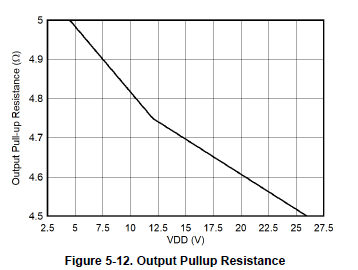

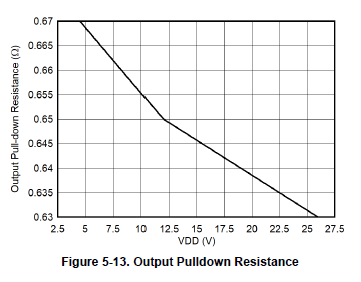

GDT_Driver_mfgpn = "UCC27524";
%GDT_Driver_topology = "unipolar"; % Single-ended, GND to VCC
GDT_Driver_topology = "bipolar";  % Push/pull, -VCC to +VCC

V_gdt_drive = 12;        % GDT drive voltage, V
R_ext_gdt_driver = 15;   % External series resistance, Ohms

% Desired time for series coupling capacitor to reach its steady state
% voltage, Vc, when the driver starts switching
tau_coupling_cap_target = 1e-6; % seconds

% Percent tolerance for max allowed voltage drop from V_gdt_drive
% For example: Vdrop(max) <= V_gdt_drive *(1-Vdroop_gdt_pri_percent_target)
Vdroop_gdt_pri_percent_target = 0.05;       % 5 percent

switch GDT_Driver_mfgpn
    case "UCC27524"
        R_gdt_drv_pu = 4.5; % Driver internal ouput pull-up resistor, Ohm
        R_gdt_drv_pd = 0.63;    % Driver internal output pull-down resistor, Ohm
        %fprintf("GDT Driver MFG P/N: %s\n",GDT_Driver_mfgpn);
    otherwise
        error("Invalid GDT Driver MFG P/N: %s\n",GDT_Driver_mfgpn);
end

%fprintf("GDT Driver Topology: %s\n", GDT_Driver_topology);

## HV Bus Parameters

VbusCap_mfgpn = "ALS70A362KE250";

% Voltage doubler configuration: Vrms = 120VAC, Vpk = Vrms*sqrt(2)
% Vbus = 2*Vpk
Vbus_in_rms = 120;                   % AC mains in, Vrms
Vbus_in_pk = Vbus_in_rms*sqrt(2);    % AC mains pk in, Vpk  
HVBUS.Vbus = 2*Vbus_in_pk;           % Output voltage, V

% NOTE: This is a educated guess
HVBUS.Lesr = 25e-9;                   % Parasitic series inductance of voltage doubler capacitors, H

switch VbusCap_mfgpn
    case "ALS70A362KE250"
        HVBUS.Cap = 3600e-6;    % Capacitance of each capacitor, F
        HVBUS.VDC_cap = 250;    % VDC Rating of each capactior, V
        HVBUS.Iripple_cap_rating = 13.6;   % Ripple current @ 10kHz (85 C), A
        HVBUS.ESR_cap = 74e-3;  % Capacitor max ESR, Ohms
        HVBUS.R_balance = -1;   % Balance Capacitor value, set to -1 to auto-compute
        HVBUS.Ns_cap = 2;       % Number of bus capacitors in series per branch
        HVBUS.Np_cap = 1;       % Number of bus capacitor parallel branches
    otherwise
        error("ERROR: Invalid bus capacitor MFG P/N: %s\n",VbusCap_mfgpn);
end

HVBUS.Cap_eq = (HVBUS.Cap/HVBUS.Ns_cap)*HVBUS.Np_cap;             % Equivalent capacitance of voltage doubler, F
HVBUS.E_bus = ((HVBUS.Vbus^2)*HVBUS.Cap_eq)/2;                    % Compute total energy stored in bus capacitors, Joules

## Bus Bar Parameters

### Mating stub of Voltage Doubler Rev A PCB

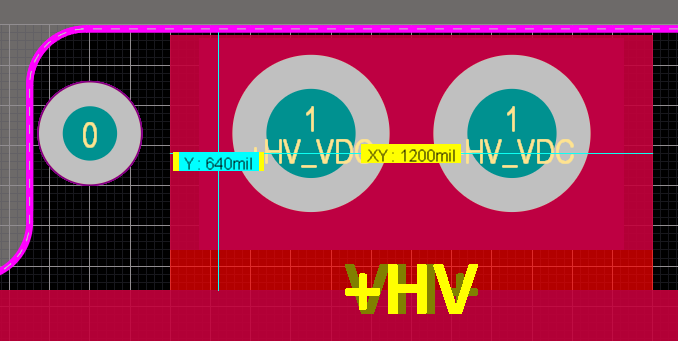

### Mating stub of Half-Bridge Rev A PCB

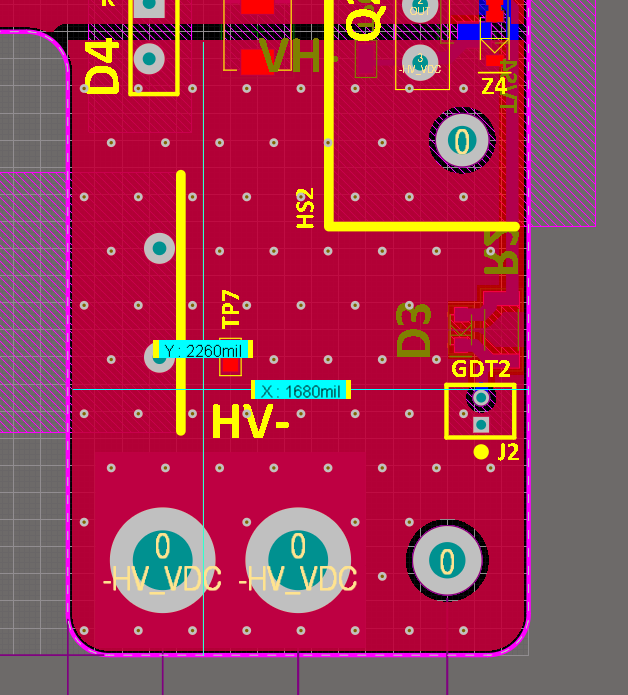

w_in = ((1200 + 1680)/2)/1000;  % Compute average conductor width and convert to in.
l_in = ((2260 + 640)/2) /1000; % Compute average conductor length and convert to in.

### Saturn PCB Design Toolkit L0 Computation

For 2 layer board, 62 mil thickness, conductor width of w (see above), 4.5 oz outside copper, and 264kHz (f_resonant) frequency.

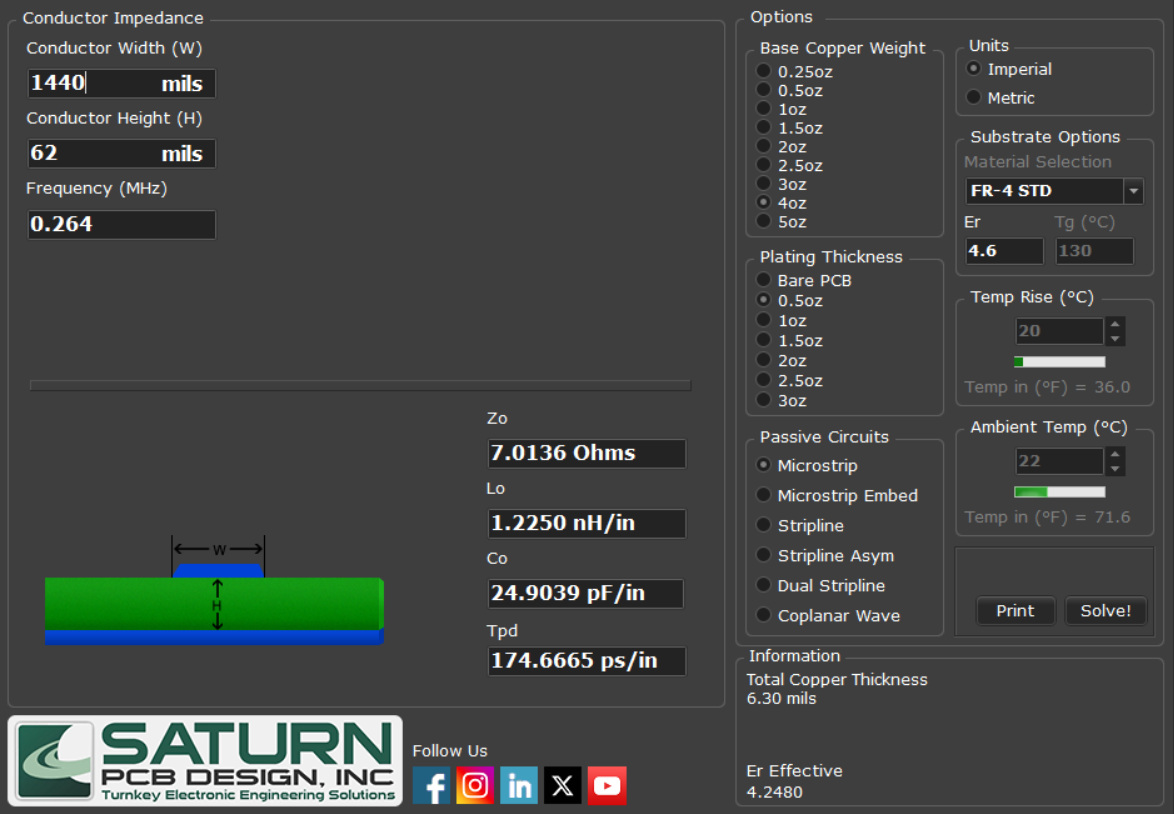


% Compute the bus bar length to m for downstream calc
% Note add 20% overhead for conservative estimate
BUSBAR.Length = CONVERSION.INCH_TO_METER*(l_in*1.20); % Bus bar length, m

% Inductance of the conductor provided by Saturn PCB Design Toolkit
L0 = 1.2250e-9; % H/in
% Compute bus rail parasitic inductances
BUSBAR.PosRail_Lpara = (CONVERSION.METER_TO_INCH*BUSBAR.Length)*L0; % H
BUSBAR.NegRail_Lpara = (CONVERSION.METER_TO_INCH*BUSBAR.Length)*L0; % H


## Bridge Parameters

#### Part number: [B32774X4505K000](https://www.digikey.com/en/products/detail/epcos-tdk-electronics/B32774X4505K000/10468626)

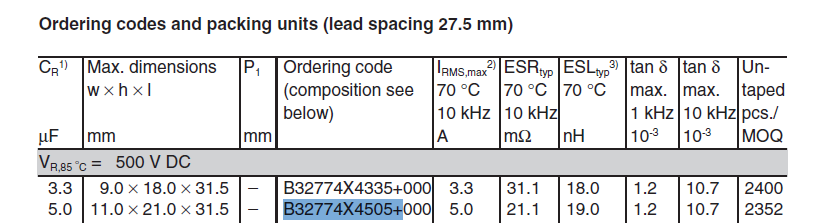

#### Part number: [C4AQNLW4500M33J](https://www.digikey.com/en/products/detail/kemet/C4AQNLW4500M33J/13563478)

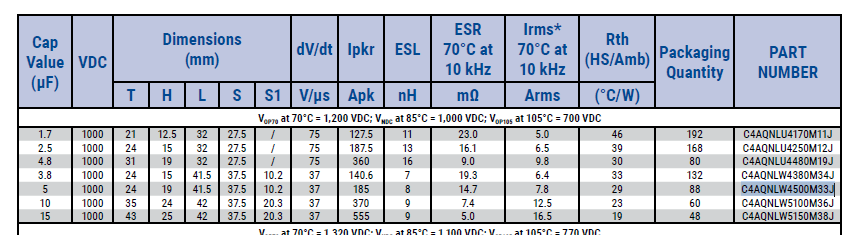

%IGBT_mfgpn = "IGW100N60H3"; % runner-up
IGBT_mfgpn = "FGA60N65SMD"; 

%Csnub_mfgpn = "B32774X4505K000" % runner-up
Csnub_mfgpn = "C4AQNLW4500M33J";

% Build snubber capacitor
INV_SNUB_CAP.mfgpn = Csnub_mfgpn;

switch Csnub_mfgpn
    case "B32774X4505K000"
        INV_SNUB_CAP.C = 5e-6;  % Capacitance, F
        INV_SNUB_CAP.VDC = 500; % Voltage rating, V
        INV_SNUB_CAP.ESL = 19e-9;   % Equivalent series inductance, H
    case "C4AQNLW4500M33J"
        INV_SNUB_CAP.C = 5e-6;  % Capacitance, F
        INV_SNUB_CAP.VDC = 1000; % Voltage rating, V
        INV_SNUB_CAP.ESL = 8e-9;   % Equivalent series inductance, H
    otherwise
        error("Invalid snubber capacitor part #: %s",Csnub_mfgpn);
end

INVERTER.topology = "full";            % full or half
INVERTER.Vbus = HVBUS.Vbus;            % Bus voltage feeding inverter bridge, V
INVERTER.OCP_limit = SYSTEM.OCD_max;   % Max allowed current in tank circuit, A
INVERTER.SnubberCap = INV_SNUB_CAP;    % Pass snubber cap to inverter

switch IGBT_mfgpn
    case "IGW100N60H3"
        IGBT.mfgpn = IGBT_mfgpn;
        IGBT.Q_g = 625.0e-9;    % IGBT gate charge, Coulomb
        IGBT.Vce_max = 600;     % Max Collector-emitter voltage, V
        IGBT.pkg_type = "TO-247";
        %fprintf("IGBT MFG P/N: %s\n",IGBT_mfgpn);
    case "FGA60N65SMD"
        IGBT.mfgpn = IGBT_mfgpn;
        IGBT.Q_g = 189.0e-9;    % IGBT gate charge, Coulomb
        IGBT.Vce_max = 650;     % Max Collector-emitter voltage, V
        IGBT.pkg_type = "TO-247";
        %fprintf("IGBT MFG P/N: %s\n",IGBT_mfgpn);
    otherwise
        error("Invalid IGBT MFG P/N: %s\n",IGBT_mfgpn);
end


## Secondary Tank Parameters

SEC_TANK.L_sec = 19.73e-3;  % Secondary inductance, H
SEC_TANK.L_sec_esr = 45.06; % Secondary ESR, Ohms

## Topload Parameters

SEC_TANK.Topload_Geometry = "toroid";

switch SEC_TANK.Topload_Geometry
    case "toroid"
        SEC_TANK.Topload_toroid_minorDiam_mm = 88.9;       % Toroid minor diameter, mm (3.5")
        SEC_TANK.Topload_toroid_majorDiam_mm = 355.6;       % Toroid major diameter, mm (14")
    otherwise
        error("Invalid topload geometry: %s\n\n",SEC_TANK.Topload_Geometry);
end

%fprintf("Topload geometry: %s\n\n",SEC_TANK.Topload_Geometry);

## Current Feedback Parameters

CURR_FB.CT_OCD_Ns = 1024; % Secondary turns for OCD current XFMR
CURR_FB.CT_ZCD_Ns = 1024; % Secondary turns for ZCD current XFMR 
CURR_FB.R_OCD_burden = 1; % OCD CT burden resistor (Ohms)
CURR_FB.R_ZCD_burden = 500e-3;  % ZCD CT burden resistor (Ohms)
CURR_FB.CT_OCD_ET = 0.002; % Current XFMR Volt-time max, V * sec (2000 V * usec)
CURR_FB.CT_ZCD_ET = 0.002; % Current XFMR Volt-time max, V * sec (2000 V * usec)

